# **Machine Learning with MATLAB**

Digital Twin & Automation

# Feature Reduction & Selection

# Feature Reduction: PCA

## **Example 1**

**Data Generation: Random normal distributed**

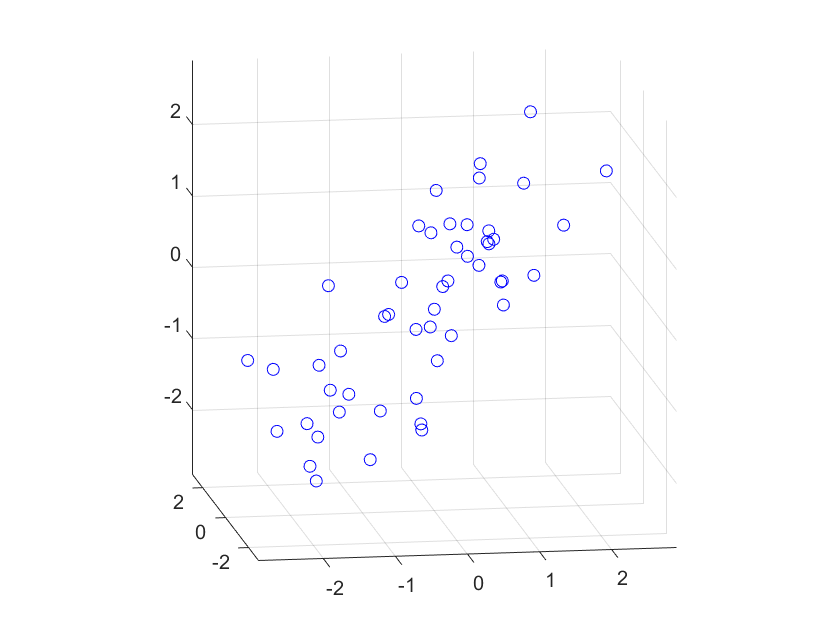

rng(5,'twister');
cwru_train = mvnrnd([0 0 0], [1 .2 .7; .2 1 0; .7 0 1],50); % multivariate normal distributed random data
plot3(cwru_train(:,1),cwru_train(:,2),cwru_train(:,3),'bo');
grid on;
maxlim = max(abs(cwru_train(:)))*1.1;
axis([-maxlim maxlim -maxlim maxlim -maxlim maxlim]);
axis square
view(-9,12);

#### **Apply PCA**

Next, we fit a plane to the data using PCA. The coefficients for the first two principal components define vectors that form a basis for the plane. 

The third PC is orthogonal to the first two, and its coefficients define the normal vector of the plane.

% coeff: Eigenvectors of X covariance matrix
% score: Converted X onto PCA basis 
% roots: Eigenvalues of X covariance matrix

%[coeff,score,roots] = pca(cwru_train);
[coeff,score,roots,~, explained, pcaCenter] = pca(cwru_train);
%pcaCenter=meanX

basis = coeff(:,1:2)

basis =     0.6774   -0.0790
    0.2193    0.9707
    0.7022   -0.2269


normal = coeff(:,3)

normal =     0.7314
   -0.0982
   -0.6749


% Percentage of roots(eigenvalue) weight
explained

explained =    62.2628
   29.7578
    7.9794


pctExplained = roots' ./ sum(roots)

pctExplained =     0.6226    0.2976    0.0798


#### Feature Reduction Analysis

The first two coordinates of the principal component scores give the projection of each point onto the plane, in the coordinate system of the plane. 

To get the coordinates of the fitted points in terms of the original coordinate system, multiply each PC coefficient vector by the corresponding score, and add back in the mean of the data. The residuals are simply the original data minus the fitted points.

[n,p] = size(cwru_train);
meanX = mean(cwru_train,1);  % 1x3

% Xfit: in original coordinate system
Xfit = repmat(meanX,n,1) + score(:,1:2)*coeff(:,1:2)';  % nx3


Plane Equation:  On the plane, Xfit, is ([x1 x2 x3] - meanX)*normal = 0. 

- The equation of the fitted plane, satisfied by each of the fitted points in Xfit, is ([x1 x2 x3] - meanX)*normal = 0. 

- The plane passes through the point `meanX`, and its perpendicular distance to the origin is `meanX*normal`. 

- The norm of the residuals:  dot product of each centered point with the normal to the plane. ( r=[x1 x2 x3] - meanX)*normal )

The fitted plane minimizes the sum of the squared errors.

error = abs((cwru_train - repmat(meanX,n,1))*normal);
sse = sum(error.^2)

sse = 15.5142

#### Plot fitted plane and residual

To visualize the fit, we can plot the plane, the original data, and their projection to the plane.

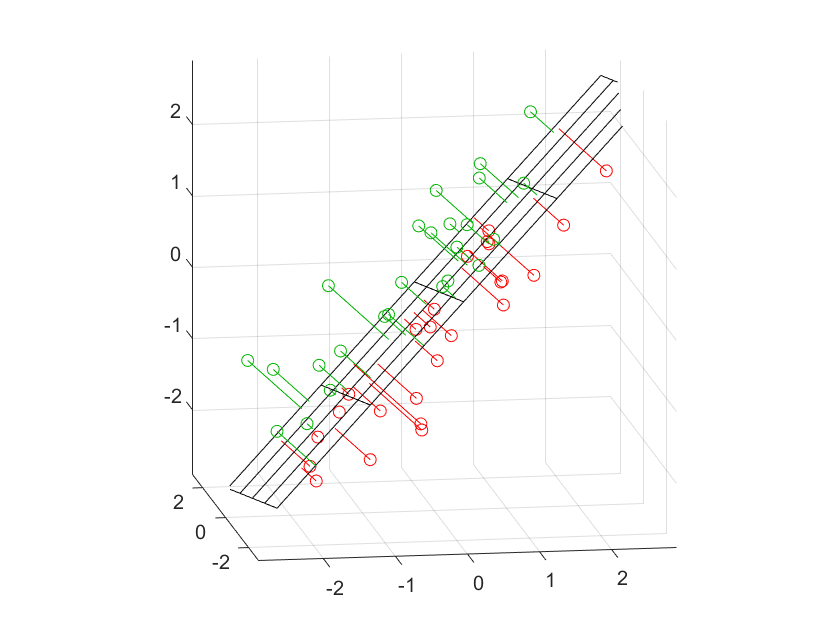

[xgrid,ygrid] = meshgrid(linspace(min(cwru_train(:,1)),max(cwru_train(:,1)),5), ...
                         linspace(min(cwru_train(:,2)),max(cwru_train(:,2)),5));

zgrid = (1/normal(3)) .* (meanX*normal - (xgrid.*normal(1) + ygrid.*normal(2)));

above = (cwru_train-repmat(meanX,n,1))*normal < 0;
nabove = sum(above);
below = ~above;
nbelow = sum(below);


h = mesh(xgrid,ygrid,zgrid,'EdgeColor',[0 0 0],'FaceAlpha',0);
hold on
X1 = [cwru_train(above,1) Xfit(above,1) nan*ones(nabove,1)];
X2 = [cwru_train(above,2) Xfit(above,2) nan*ones(nabove,1)];
X3 = [cwru_train(above,3) Xfit(above,3) nan*ones(nabove,1)];
plot3(X1',X2',X3','-', cwru_train(above,1),cwru_train(above,2),cwru_train(above,3),'o', 'Color',[0 .7 0]);
X1 = [cwru_train(below,1) Xfit(below,1) nan*ones(nbelow,1)];
X2 = [cwru_train(below,2) Xfit(below,2) nan*ones(nbelow,1)];
X3 = [cwru_train(below,3) Xfit(below,3) nan*ones(nbelow,1)];
plot3(X1',X2',X3','-', cwru_train(below,1),cwru_train(below,2),cwru_train(below,3),'o', 'Color',[1 0 0]);
hold off
maxlim = max(abs(cwru_train(:)))*1.1;
axis([-maxlim maxlim -maxlim maxlim -maxlim maxlim]);
axis square
view(-9,12);

# **Sequential Feature Selection**

Selects a subset of features from the data matrix `X` that best predict the data in `y` by sequentially selecting features until there is no improvement in prediction. 

For each candidate feature subset, `sequentialfs` performs 10-fold cross-validation by repeatedly calling `fun` with different training subsets of `X` and `y`, `XTRAIN` and `ytrain`, and test subsets of `X` and `y`, `XTEST` and `ytest`, as follows:

`criterion = fun(XTRAIN,ytrain,XTEST,ytest)`

`Backward Selection`

`inmodel = sequentialfs(fun,X,y,'direction', 'backward'` )

## Example 1: Fisher Iris

load fisheriris
rng('default') % For reproducibility
cwru_train = randn(150,10);
cwru_train(:,[1 3 5 7])= meas;
y = species;

c = cvpartition(y,'k',10);
opts = statset('Display','iter');


#### Feature Selection

%  fitcecoc(): Fit multiclass models for support vector machines 
fun = @(XT,yT,Xt,yt)loss(fitcecoc(XT,yT),Xt,yt);

[fs,history] = sequentialfs(fun,cwru_train,y,'cv',c,'options',opts)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 7번 열 추가, 기준값 0.00266667
2단계, 5번 열 추가, 기준값 0.00222222
3단계, 1번 열 추가, 기준값 0.00177778
4단계, 3번 열 추가, 기준값 0.000888889
최종적으로 포함된 열: 1 3 5 7 


fs = 1×10 logical 배열
   1   0   1   0   1   0   1   0   0   0


history = 다음 필드를 포함한 struct :
      In: [4×10 logical]
    Crit: [0.0027 0.0022 0.0018 8.8889e-04]


#### Train SVM model

mdl = fitcecoc(cwru_train, y);
idx = find(fs);
mdl_select = fitcecoc(cwru_train(:, idx), y);

#### K-fold Loss and Confusion matrix

accuracy = 1 - kfoldLoss(crossval(mdl))

accuracy = 0.9600

accuracy = 1 - kfoldLoss(crossval(mdl_select))

accuracy = 0.9800

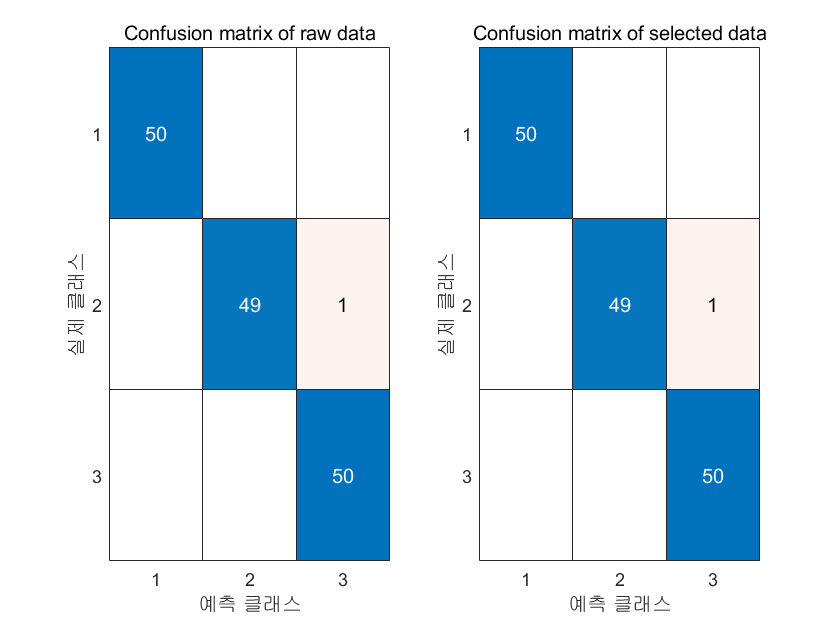

y_pred        = predict(mdl, cwru_train);
y_pred_select = predict(mdl_select, cwru_train(:, idx));

C = confusionmat(y, y_pred);
C_select = confusionmat(y, y_pred_select);

figure
subplot(1, 2, 1);   confusionchart(C);          title("Confusion matrix of raw data");
subplot(1, 2, 2);   confusionchart(C_select);   title("Confusion matrix of selected data");

## Example 2: CWRU features

### Data Acquisition

- Given dataset contains many features extracted from CWRU dataset

- We will all  features for exercise

%% Train
load("../CWRU_dataset/CWRU_features/example_train.mat");

%% Test
load("../CWRU_dataset/CWRU_features/example_test.mat");



% Select Features to use 
feature_idx = [4,9,14,17,20,22,26,27,32,35,41];

cwru_train = table2array(glob_all_train(:, feature_idx));
cwru_test  = table2array(glob_all_test(:, feature_idx));
class_train = categorical(class_cwru_train);
class_test  = categorical(class_cwru_test);

### Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)
Y = height(cwru_train);         % Size of table
cv = cvpartition(Y,'KFold',10)  % k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

### (Option1) Feature Selection 

% Feature의 성능을 평가하기 위한 loss function 설정

lossfun = 'mincost';

%%% For SVM
fun = @(XT,yT,Xt,yt)loss(fitcecoc(XT,yT),Xt,yt, 'Lossfun', lossfun);    % svm 이용

%%% For KNN
% k =10;
% fun = @(XT,yT,Xt,yt)loss(fitcknn(XT,yT, 'NumNeighbors', k, 'Standardize', ...
%     1),Xt,yt, 'Lossfun', lossfun);                                      % knn 이용

% dir = 'forward';
dir = 'backward';                        % direction of selection(forward/backward)
opts = statset('Display','iter');
[inmodel, history] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir)

역방향 순차적 특징 선택 시작:
포함된 초기 열: all
포함해야 할 열: none
1단계, 초기 열 사용, 기준값 0.00170264
2단계, 3번 열 제거, 기준값 0.00162406
3단계, 4번 열 제거, 기준값 0.00150558
최종적으로 포함된 열: 1 2 5 6 7 8 9 10 11 


inmodel = 1×11 logical 배열
   1   1   0   0   1   1   1   1   1   1   1


history = 다음 필드를 포함한 struct :
      In: [3×11 logical]
    Crit: [0.0017 0.0016 0.0015]


Loss function의 종류:

'binodeviance'    Binomial deviance

'classiferror'        Misclassified rate in decimal

'exponential'        Exponential loss

'hinge'                Hinge loss

'logit'                  Logistic loss

'mincost'             Minimal expected misclassification cost (for classification scores that are posterior probabilities)

'quadratic'           Quadratic loss

#### K-fold Loss of All features vs Selected features

% K-fold Loss of all  features
mdl = fitcecoc(cwru_train, class_train);
cvmdl = crossval(mdl); % Performs stratified 10-fold cross-validation
accuracy = 1 - kfoldLoss(cvmdl)

accuracy = 0.9236



% K-fold Loss of selected features
idx_select = find(inmodel);     
cwru_train_select  = cwru_train(:, idx_select);
cwru_test_select  = cwru_test(:, idx_select);

mdl_select = fitcecoc(cwru_train_select, class_train);
cvmdl_select = crossval(mdl_select); 
accuracy_select = 1 - kfoldLoss(cvmdl_select)

accuracy_select = 0.9213

#### Loss of Test Dataset: All features vs Selected features

% Test Loss of all  features
error = loss(mdl, cwru_test, class_test);
accuracy = 1-error

accuracy = 0.9444


% Test Loss of selected  features
error_select = loss(mdl_select, cwru_test_select,class_test);
accuracy_select = 1-error_select

accuracy_select = 0.9537

### (Option 2) Manually select feature number 

#### Plot Accuracy vs feature number selection

rng(0)
% 전체 feature가 선택/제외될때까지 selection 진행
dir = 'forward';    nfeat = length(cwru_train(1, :));
% dir = 'backward';   nfeat = 1;    % nfeat: number of features at which sequentialfs should stop
[inmodel, history] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir, 'nfeatures', nfeat)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 9번 열 추가, 기준값 0.00479725
2단계, 1번 열 추가, 기준값 0.00223331
3단계, 5번 열 추가, 기준값 0.0021104
4단계, 4번 열 추가, 기준값 0.00175028
5단계, 8번 열 추가, 기준값 0.00174542
6단계, 6번 열 추가, 기준값 0.00171411
7단계, 2번 열 추가, 기준값 0.00172006
8단계, 10번 열 추가, 기준값 0.00153098
9단계, 7번 열 추가, 기준값 0.00157263
10단계, 11번 열 추가, 기준값 0.00162406
11단계, 3번 열 추가, 기준값 0.00170264
최종적으로 포함된 열: all


inmodel = 1×11 logical 배열
   1   1   1   1   1   1   1   1   1   1   1


history = 다음 필드를 포함한 struct :
      In: [11×11 logical]
    Crit: [0.0048 0.0022 0.0021 0.0018 0.0017 0.0017 0.0017 0.0015 0.0016 0.0016 0.0017]


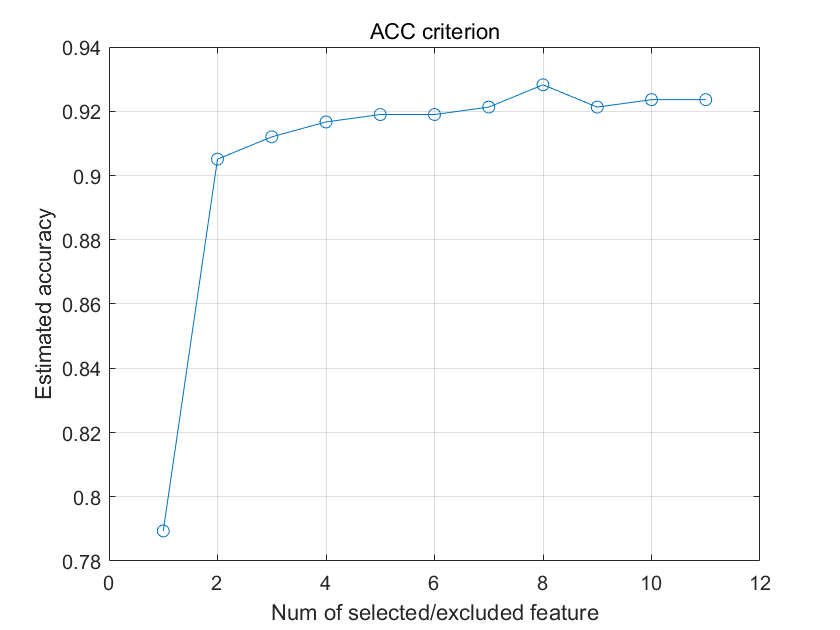

% Accuracy during feataure selection/exclusion
feat_num = length(history.In(:,1));
accuracy_hst = zeros(feat_num, 1);

for i=1:feat_num
    idx_hst = find(history.In(i, :));   % hitory: feature를 선택/제외한 전체 기록
    mdl_hst = fitcecoc(cwru_train(:,idx_hst), class_train);
    cvmdl_hst = crossval(mdl_hst); % Performs stratified 10-fold cross-validation
    accuracy_hst(i) = 1 - kfoldLoss(cvmdl_hst);
end
figure
plot(accuracy_hst, '-o'); title("ACC criterion");   grid on;
xlabel("Num of selected/excluded feature"); ylabel("Estimated accuracy");

### Select feature number : e.g. 8

% Selected features of Test data
fselect=8;
idx_select = find(history.In(fselect, :));      % hitory: feature를 선택/제외한 전체 기록
cwru_train_select  = cwru_train(:, idx_select);
cwru_test_select  = cwru_test(:, idx_select);   


### Loss of Test Dataset: All features vs Selected features

% Test Loss of All  features
% mdl = fitcecoc(cwru_train, class_train);
error = loss(mdl, cwru_test, class_test);
accuracy = 1-error

accuracy = 0.9444


% Test Loss of Selected features
mdl_select = fitcecoc(cwru_train_select, class_train);
error_select = loss(mdl_select, cwru_test_select,class_test);
accuracy_select = 1-error_select

accuracy_select = 0.9444

# Exercise

## Exercise :   CWRU data with PCA reduction vs Sequential Feature Selection

- Apply PCA  on CWRU dataset.

- Analyze the coefficient and score of PCA.  

- Apply 95%  coefficients importance for reduction.  (5 dimension for this case)

- Train SVM with PCA reduced train dataset

- Loss of Test dataset

- Compare Test Loss with Sequential Feature Selection

### Data Acquisition

- Given dataset contains many features extracted from CWRU dataset

- We will all  features for exercise

%% Train
load("../CWRU_dataset/CWRU_features/example_train.mat");

%% Test
load("../CWRU_dataset/CWRU_features/example_test.mat");



% Select 11 Features to use 
feature_idx = [4,9,14,17,20,22,26,27,32,35,41];

cwru_train = table2array(glob_all_train(:, feature_idx));
cwru_test  = table2array(glob_all_test(:, feature_idx));
class_train = categorical(class_cwru_train);
class_test  = categorical(class_cwru_test);


### Apply PCA

rng(0)

%%% Your Code goes here
% [coeff, scores_train, ~, ~, explained, pcaCenter] = ____________


#### Select  PCA coefficient with 95% importance

% Returns Explained, the percentage of the total variance explained by each principal component
% explained
% 최소 95%의 변동성을 설명하는데 필요한 성분의 개수

explain_standard = .95;     
num = find(cumsum(explained)/sum(explained) >= explain_standard, 1)

#### Feature Reduction Analysis

coeff = coeff(:,1:num);
scores_train = scores_train(:,1:num);

[n,p] = size(cwru_train);
meanX = mean(cwru_train,1);


% Xfit: in original coordinate system
Xfit = repmat(meanX,n,1) + scores_train(:,1:num)*coeff(:,1:num)';


#### Plot fitted plane and residual

To visualize the fit, we can plot the plane, the original data, and their projection to the plane.

- For this example, we will use 3 dimension

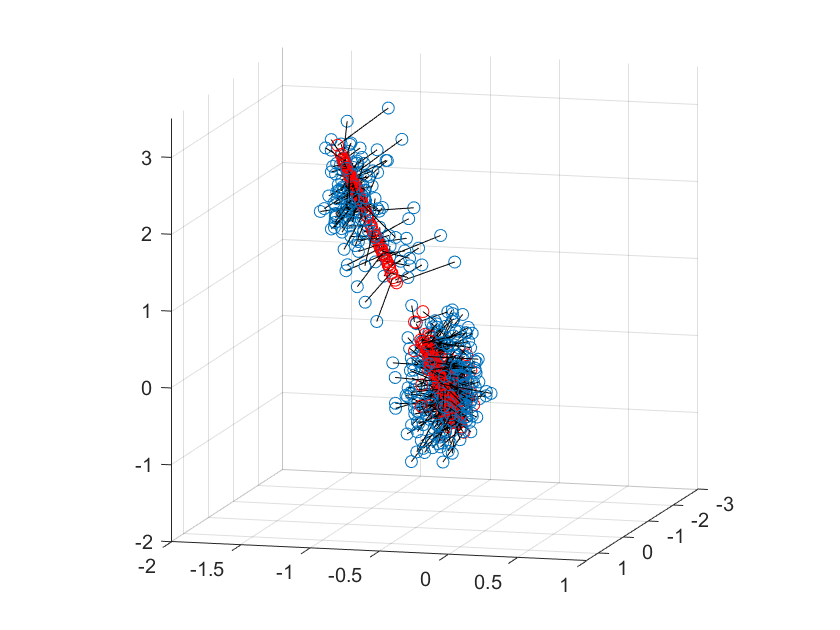

figure
hold on
plot3(cwru_train(:, 1),cwru_train(:, 2),cwru_train(:, 3), 'o');
X1 = [cwru_train(:, 1), Xfit(:, 1), nan*ones(length(cwru_train), 1)];
X2 = [cwru_train(:, 2), Xfit(:, 2), nan*ones(length(cwru_train), 1)];
X3 = [cwru_train(:, 3), Xfit(:, 3), nan*ones(length(cwru_train), 1)];
plot3(X1', X2', X3', '-k', Xfit(:, 1),Xfit(:, 2),Xfit(:, 3), 'or')
grid on

axis([-3 1.5 -2 1 -2 3.5]);
axis square
view(105,10);

### Train SVM model: PCA data

% Apply multi-class SVM on PCA scores_train

%%% YOUR CODE GOES HERE
% mdl_pca = ___________


### K-fold Loss : PCA vs Feature Selection

% kfold accuracy of PCA
%%% YOUR CODE GOES HERE
% cvmdl_pca = ______________
% accuracy_pca = ___________________


% kfold accuracy of selection
%%% YOUR CODE GOES HERE
% accuracy_select = ______________

### Covert Test data to PCA reduced dimension

Convert Test data from originial coordinate to PCA vectors

% cwru_test_pca:  Test data in PCA coefficent vectors
% Convert Test data from originial coordinate to PCA vectors
%  X_pca=(X-meanX)*inv(coeff')

[ntest,ptest] = size(cwru_test);
mu = repmat(pcaCenter, ntest, 1);
cwru_test_pca = (cwru_test - mu)/coeff';


### Confusion Matrix : PCA vs Feature Selection

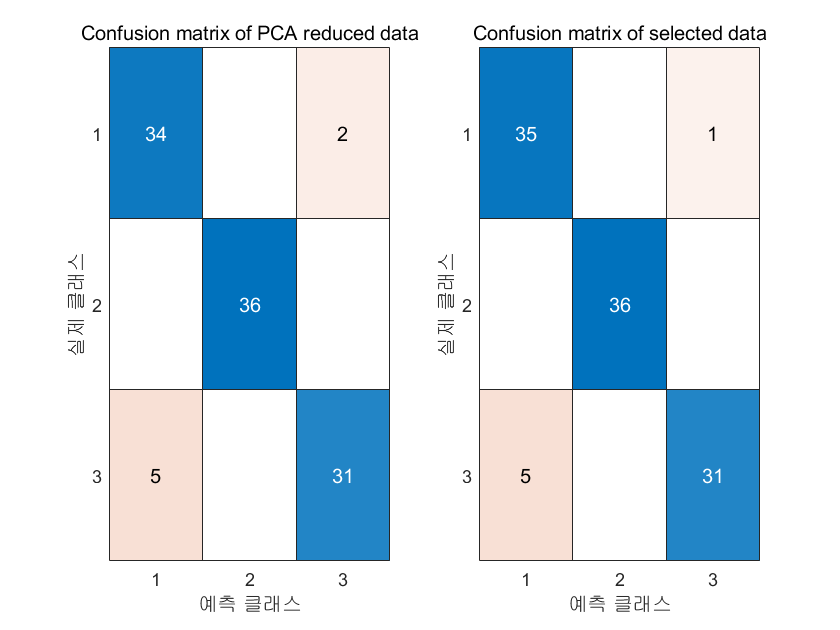

% Calculate Confusion matrix

%%% YOUR CODE GOES HERE
% class_pca    = predict(______________)
% class_select = ____________________

% C_pca = confusionmat(__________);
% C_select = _______________________

% Plot Confusion Matrix
figure
subplot(1, 2, 1);   confusionchart(C_pca);          title("Confusion matrix of PCA reduced data");
subplot(1, 2, 2);   confusionchart(C_select);       title("Confusion matrix of selected data");